clc, clearvars, close all

## We need to define our function and its derivative

f = @(z) 2*z.^6 - 18*z;
h = 1e-12;
df = @(z) (f(z+h)-f(z))/h;

The algorythem will give different results based on the starting value

z0 = 50+ 0*1i;
NewtonsMethod(f,df,z0)

ans = 1.5518

When applying the algorythem to the complex plain we can generate a fractal based on which root each point converge to

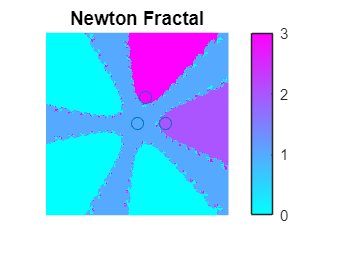

resolution1 = "600";
Roots_array = Newton_Fractal_Roots(f,df,resolution1);

Or we can color it based on how long it takes for each point to converge

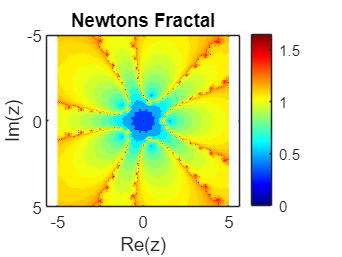

resolution2 = "1200";
Convergence_array = Newton_Fractal_Convergence(f,df,resolution2);

We can use the box counting method to estimate the fractal dimension of each of them

Binary_Roots =  zeros(size(Roots_array));
Binary_Roots(:,:)=Roots_array(:,:)>0;
Binary_Convergence =  zeros(size(Convergence_array));
Binary_Convergence(:,:)=Convergence_array(:,:)>15;

FractalDim(Binary_Roots)

ans = 1.8525

FractalDim(Binary_Convergence)

ans = 1.4991

## The functions used in the project

function [function_root, num_iterations] = NewtonsMethod(f, df, z0, tolerance, max_iters)
%NewtonsMethod Finding the roots of a function

%   A function that uses Newton's method to find the roots of a polynomial,
%   but generalized to any function, including complex ones


%Defining the defult extra inputs: tolerance and maximum number of itterations

if nargin == 3
    tolerance = 1e-6;
    max_iters = 100;
end

if nargin == 4
    max_iters = 100;
end


num_iterations = 0;

while num_iterations < max_iters
    if abs(df(z0)) < eps
        function_root = NaN;
        return;
    end
    
    z1 = z0 - f(z0) / df(z0);

    if abs(z0 - z1) < tolerance
        function_root = z1;
        return;
    end

    z0 = z1;
    num_iterations = num_iterations + 1;
end

function_root = NaN;

end


function [Fractal_matrix] =  Newton_Fractal_Roots(f, df, resolution, xmin, xmax, ymin, ymax)
%Newton_Fractal_Roots Creating the Newton Fractal
%   The function creates a figure containing the Newton Fractal colored
%   based on which root each point converges to 


if nargin == 2
    resolution = 600;
    xmin = -5;
    xmax = 5;
    ymin = -5;
    ymax = 5;
end

if nargin == 3
    xmin = -5;
    xmax = 5;
    ymin = -5;
    ymax = 5;
end

max_iter = 100; % Maximum number of iterations
tolerance = 1e-6;    % Tolerance for convergence


% Set up the complex plane grid
x = linspace(xmin, xmax, resolution);
y = linspace(ymin, ymax, resolution);
[X, Y] = meshgrid(x, y);
Z = X + 1i*Y;

% Roots of the function
roots_f = [];
for n = 0:20
    current_solution = NewtonsMethod(f, df, exp(1i*n/pi), 1e-6, 100);
    if ~any(abs(roots_f - current_solution) < 1e-6)
        roots_f(end+1) = current_solution;
    end
end
roots_f = roots_f(~isnan(roots_f));

% Initialize the convergence matrix
C = zeros(size(Z));
iter_count = zeros(size(Z)); % To store the iteration count for coloring

% Iterate using Newton's method
for k = 1:max_iter
    Z = Z - f(Z)./df(Z);
    for j = 1:length(roots_f)
        mask = abs(Z - roots_f(j)) < tolerance;
        C(mask & C == 0) = j;
        iter_count(mask & iter_count == 0) = k;
    end
end

% Normalize the iteration count for better coloring
iter_count(iter_count == 0) = max_iter;


% Plot the fractal
figure;
hold on
imagesc(x, y, C);
scatter(real(roots_f), imag(roots_f))
axis off;
colormap("cool")
colorbar;
axis equal;
xlabel('Re(z)');
ylabel('Im(z)');
title('Newton Fractal');

Fractal_matrix = C;
end

function [Fractal_matrix] = Newton_Fractal_Convergence(f, df, resolution, xmin, xmax, ymin, ymax)
%Newton_Fractal_Convergence Creating the Newton Fractal
%   The function creates a figure containing the Newton Fractal colored
%   based on how fast each point converges to a root

if nargin == 2
    resolution = 600;
    xmin = -5;
    xmax = 5;
    ymin = -5;
    ymax = 5;
end

if nargin == 3
    xmin = -5;
    xmax = 5;
    ymin = -5;
    ymax = 5;
end

tolerance = 1e-6;
maxIterations = 100;

% Create a grid of complex numbers
[X, Y] = meshgrid(linspace(xmin, xmax, resolution), linspace(ymin, ymax, resolution));
Z = X + 1i * Y;

% Initialize the matrix to store the number of iterations
iterations = zeros(size(Z));

% Iterate over each point in the grid
for k = 1:maxIterations
    % Calculate the function and its derivative at all points
    F = f(Z);
    DF = df(Z);
    
    % Update the points using Newton's method
    Z = Z - F ./ DF;
    
    % Check for convergence
    converged = abs(F) < tolerance;
    
    % Increment the iteration count for points that have not yet converged
    iterations(~converged) = iterations(~converged) + 1;
    
    % Break if all points have converged
    if all(converged, 'all')
        break;
    end
end

Fractal_matrix = iterations;

% Plot the fractal
figure
imagesc(linspace(xmin, xmax, resolution), linspace(ymin, ymax, resolution), log10(iterations));
colormap(jet);
colorbar;
axis equal;
xlabel('Re(z)');
ylabel('Im(z)');
title('Newtons Fractal');

end



function D = FractalDim(A)
%FractalDim Calculates the fractal dimension
%   Calculating the fractal dimension using the box counting method

FinerGrid = 8;

box_num = 4;  % Initial number of boxes
BoxesTouched = [];  % Array to store the count of boxes that touch a '1'

% Get the size of the binary matrix
[height, width] = size(A);

% Loop for different box sizes
for i = 1:FinerGrid
    count = 0;  % Initialize the count for this box size
    
    % Calculate the number of boxes along one dimension
    num_boxes = 2^(i-1);
    box_size = floor(height / num_boxes);  % Assuming height == width for simplicity
    
    % Iterate over each box
    for BoxRow = 1:num_boxes
        for BoxColumn = 1:num_boxes
            
            % Determine the starting and ending indices for the current box
            startRow = (BoxRow-1) * box_size + 1;
            endRow = min(BoxRow * box_size, height);  % Ensure the index does not exceed matrix size
            startCol = (BoxColumn-1) * box_size + 1;
            endCol = min(BoxColumn * box_size, width);  % Ensure the index does not exceed matrix size
            
            % Check if the box contains a '1'
            if any(any(A(startRow:endRow, startCol:endCol) == 1))
                count = count + 1;
            end
        end
    end
    
    % Store the count of boxes that contain '1'
    BoxesTouched(i) = count;
end


P = polyfit(1:FinerGrid,log2(BoxesTouched),1);
D = P(1);
end